Zl=120+60j;
norm1=0.01:0.01:2;
nVar=6;
LB=[0,0.05,0.05,0,0,0];
UB=[1,1,1,1,1,1];

ga stopped by the output or plot function. The reason for stopping: 
Stop requested from plot function.


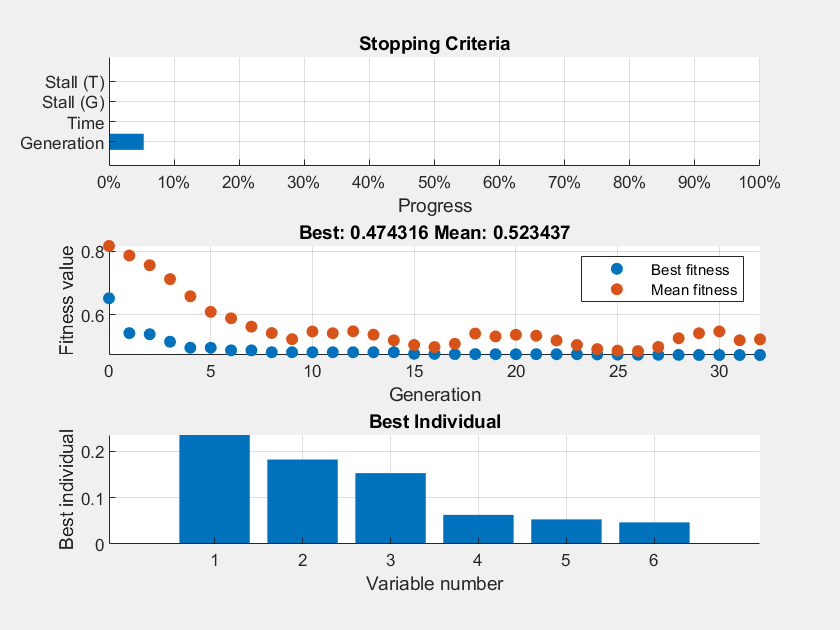

% Pass fixed parameters to objfun
objfun2 = @(p)getgsum(p,Zl,norm1);

% Set nondefault solver options
options2 = optimoptions("ga","PopulationSize",200,"MaxStallGenerations",500,...
    "MaxStallTime",200,"PlotFcn",["gaplotstopping","gaplotbestf",...
    "gaplotbestindiv"]);

% Solve
[solution2,objectiveValue2] = ga(objfun2,nVar,[],[],[],[],LB,UB,[],[],options2);


% Clear variables
clearvars objfun2 options2
p=solution2;
disp(p);

    0.2356    0.1827    0.1531    0.0630    0.0531    0.0467



disp(objectiveValue2);

    0.4743



G=getgsum1(p,Zl,0.01:0.01:2);

ZL = 1.2000e+02 + 6.0000e+01i

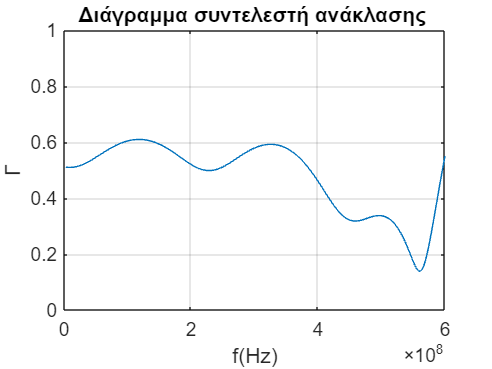

normf=[0.01:0.01:2];
f=3*10^(8)*normf;
figure 
plot(f,G);
title('Διάγραμμα συντελεστή ανάκλασης ');
xlabel('f(Hz)');
ylabel('Γ');
ylim([0 1]);
grid on;

function G=getgsum1(p,Zl,normF)
fo = 0.3*10^(9);
co=fo;
Zo=50;
normf = [0.01:0.01:2];
bignum=1000000000000000000000;
b=2*pi.*normf*fo/co;
ZL=Zl
Zin=ZL;
for i=[1:3]
    Zin1=zin(p(i),Zin,b,Zo);
    Zin2=zin(p(i+3),bignum,b,Zo);
    Zin=parallel(Zin1,Zin2);
end
G=abs((Zin-Zo)./(Zin+Zo));
end


function Zin=zin(li,Zli,b,Zo)
Zin = Zo*(Zli+1j*Zo*tan(b*li))./(Zo+1j*Zli.*tan(b*li));
end
function Par=parallel(Z1,Z2)
Par=(Z1.*Z2)./(Z1+Z2);
end
